Eksamens nr 185432                      M4TRM1-03                  Termodynamik  12-06-2023                  

clear all
clf

% Importer CoolProp-modul
CoolProp = py.importlib.import_module('CoolProp.CoolProp');

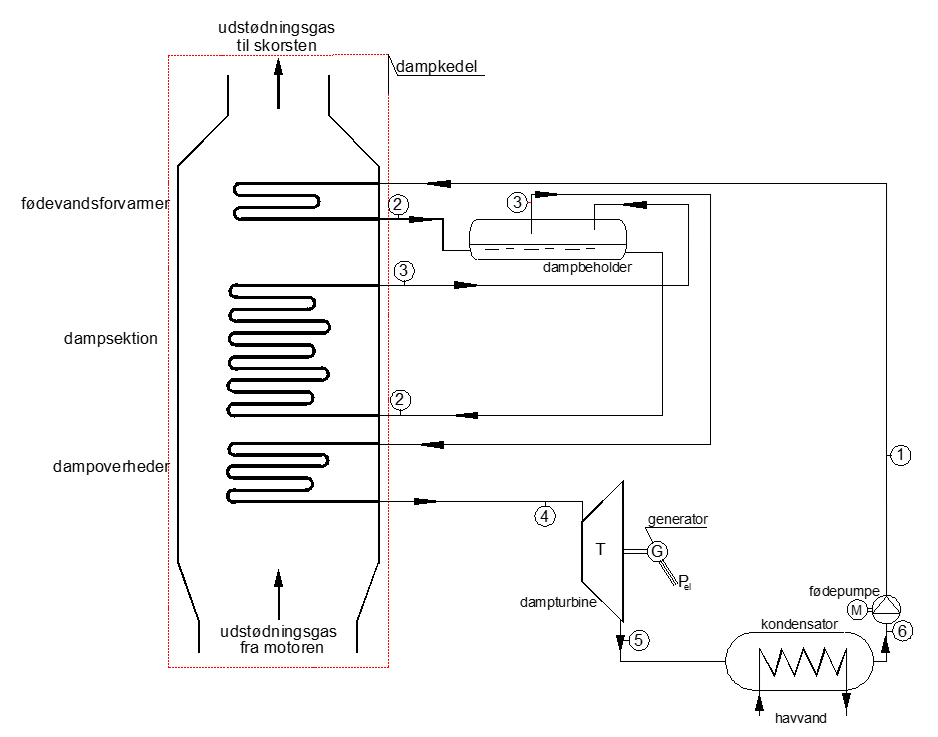

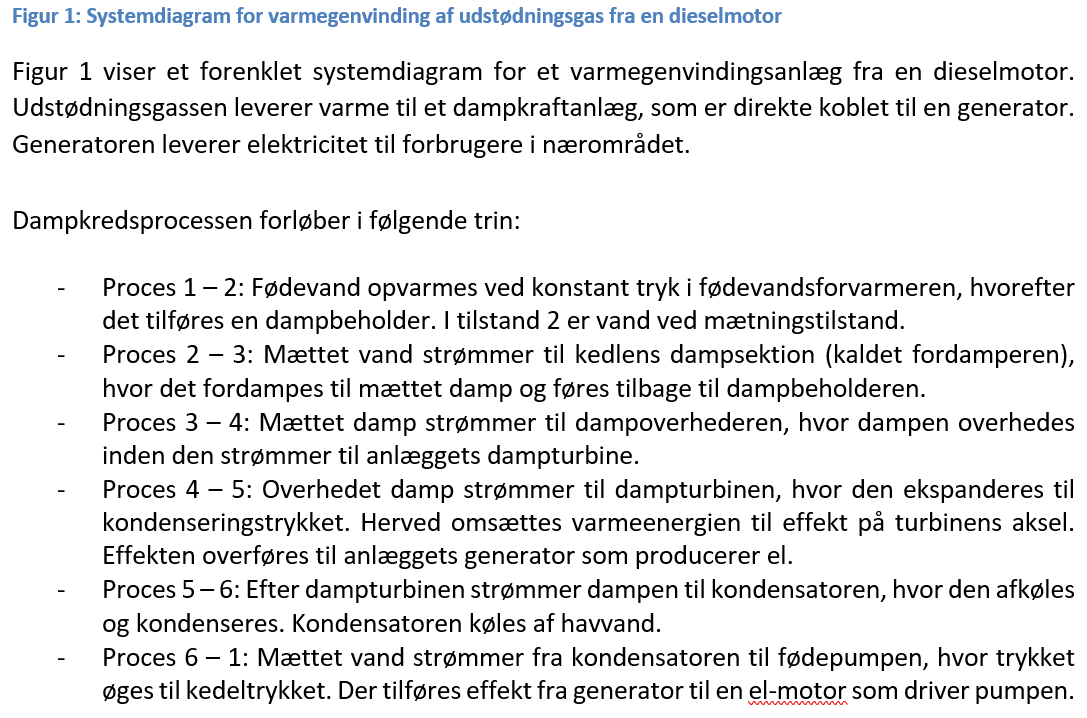

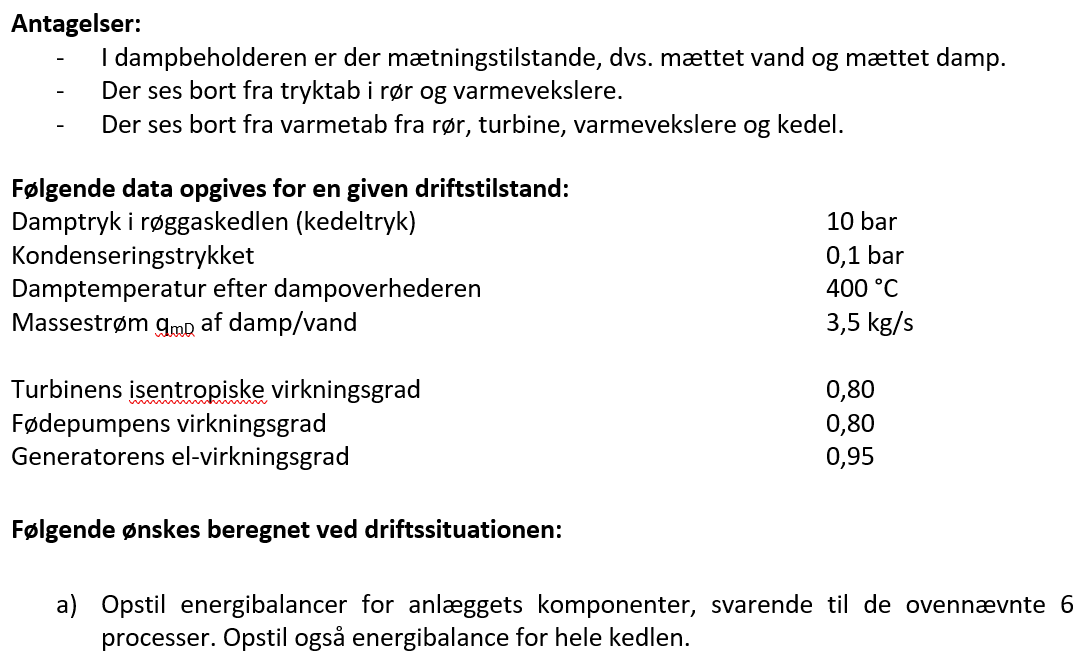

**For hele kedlen**


$$E_{ind} = E_{ud} \\
\Phi_{fvf} + \Phi_{ds} + \Phi_{do} + P_{pumpe} = P_T + \Phi_K$$


**For de 6 kontrol flader**

syms q_mD h_1 h_2 h_3 h_4 h_5 h_6 Phi_fvf Phi_K Phi_ds Phi_do P_T P_pump
eq_1_fvf = q_mD * (h_1-h_2) + Phi_fvf == 0 % Fødevandsforvarmer

$$eq\_1\_fvf = \Phi_{\mathrm{fvf}}+q_{\mathrm{mD}}\,\left(h_{1}-h_{2}\right)=0$$

eq_2_ds = q_mD * (h_2-h_3) + Phi_ds == 0 % dampsektion

$$eq\_2\_ds = \Phi_{\mathrm{ds}}+q_{\mathrm{mD}}\,\left(h_{2}-h_{3}\right)=0$$

 eq_3_do = q_mD * (h_3-h_4) + Phi_do == 0 % dampoverheder

$$eq\_3\_do = \Phi_{\mathrm{do}}+q_{\mathrm{mD}}\,\left(h_{3}-h_{4}\right)=0$$

eq_4_T = (h_4-h_5)*q_mD - P_T == 0% Turbine

$$eq\_4\_T = q_{\mathrm{mD}}\,\left(h_{4}-h_{5}\right)-P_{T}=0$$

eq_5_K = q_mD * (h_5-h_6)- Phi_K == 0 % Kondensator

$$eq\_5\_K = q_{\mathrm{mD}}\,\left(h_{5}-h_{6}\right)-\Phi_{K}=0$$

eq_6_Pump = q_mD * (h_6-h_1) + P_pump == 0

$$eq\_6\_Pump = P_{\mathrm{pump}}-q_{\mathrm{mD}}\,\left(h_{1}-h_{6}\right)=0$$

### b) Optegn *turbineprocessen*i *h,s*-diagram for vanddamp og bestem i samme forbindelse h5 og dampkvaliteten (dampindholdet) x5. Ved løsningen af opgaven benyttes enten vedlagte bilag 1 eller EES. h,s-diagrammet vedhæftes opgaveløsningen

Opgaven løses i EES. 

Vi opstiller nøgleværdier i de 6 områder samt energiligninger. Alle inthalpier og entropier kan nu findes og tegnes i h-s diagrammet

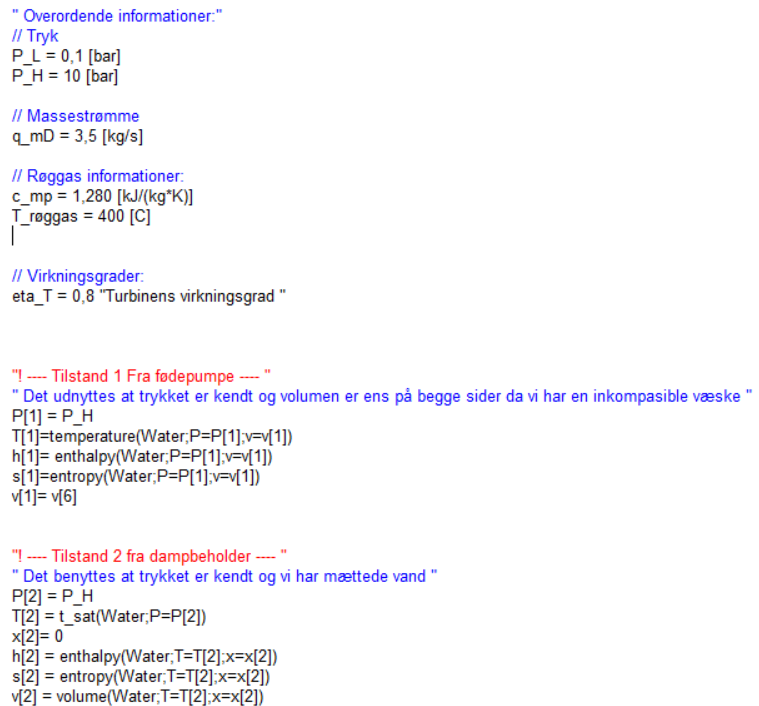

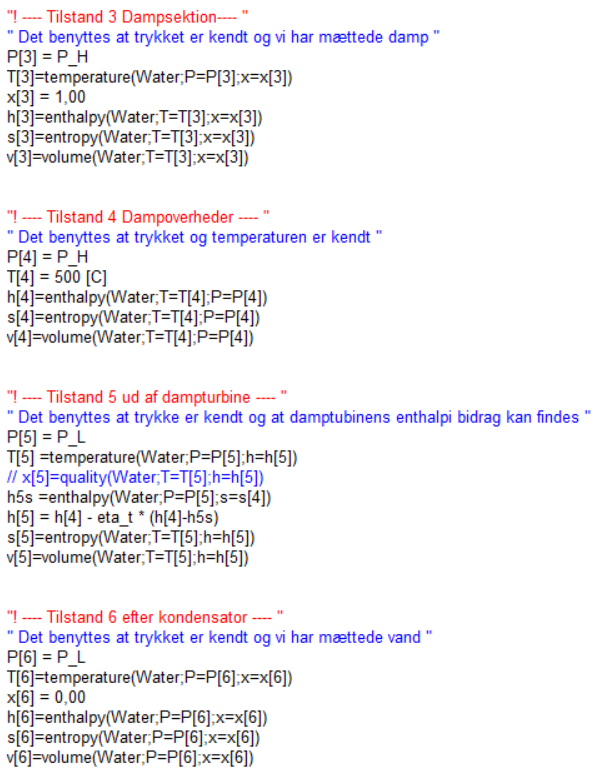

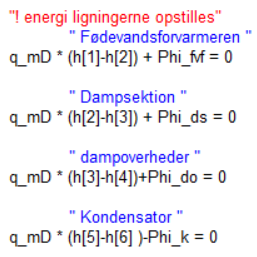

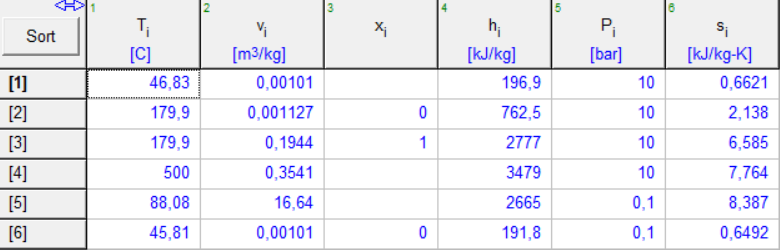

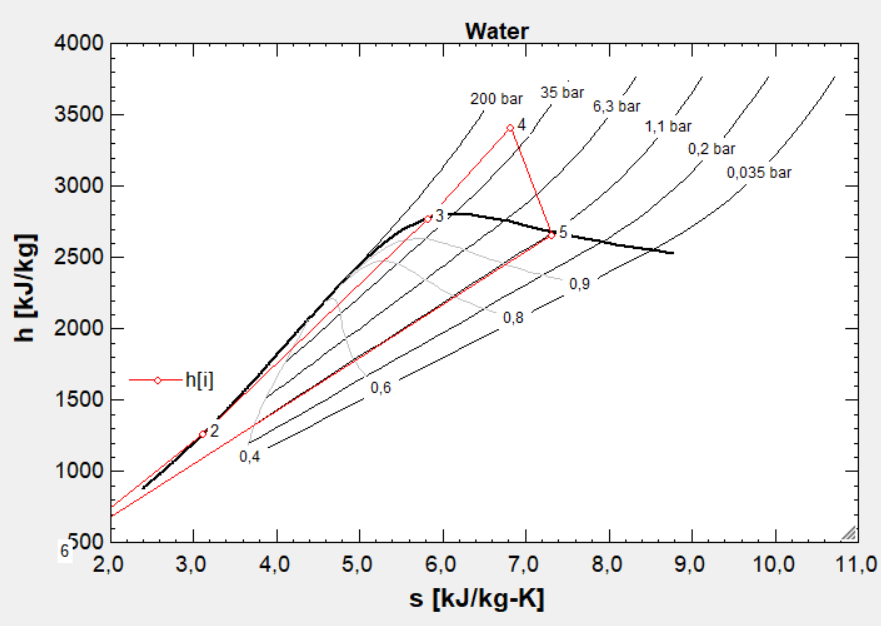

### c)Beregn afgiven effekt fra turbine og fra generator

Ved hjælp af energiligningen for turbinen kan vi finde dennes aksel effekt til generatoren

% Værdier gevet i opgaven og fundet i EES (opgave b)
fluid = 'Water';% Stof

P_kedel = 10 * 1e5;
P_5 = 0.1 * 1e5;
P_6 = P_5;
q_mD = 3.5;
T_4 = 400 + 273.15;
eta_is_T = 0.8;
eta_pumpe = 0.8;
eta_gen = 0.95;

h_4 = 3479 * 1e3;
h_5 = 2665 * 1e3;

Vi opstiller energiligningen for turbinen.

P_T = (h_4-h_5) * q_mD

P_T = 2849000

P_G = P_T * eta_gen

P_G = 2706550

Den afgevne effekt fra turbinen er således


$$P_T = 2849\ \text{kW}$$


 Generatorens producerede El effekt er således


$$P_G = 2707\ \text{kW}$$


### d) Bestem vandets tryk og specifik entalpi i punkterne 6 og 1 og beregn effekten afsat i fødepumpen

Fra opgave **b **kender vi enthalpierne

h_1 = 196.9 * 1e3;
h_6 = 191.8 * 1e3;

Vi kan nu benytte energiligningen for pumpen

% q_mD * (h_6-h_1) + P_pump == 0
P_pump = q_mD * (h_1-h_6)

P_pump = 17850

Effekten afsat i pumpen er således $P_{pumpe} = 17,850\ \text{kW}$ 

### e) Beregn hvor stor en andel af varmestrømmen fra kedlen, der leveres til forbrugerne i form af el-effekt, også benævnt processens termiske virkningsgrad.

Vi dinder den termiske virkningsgrad med ligning 6.16 fra lærebogen.

Fra energiligningerne i opgave **b** for vi

Phi_fvf = 1980 * 1e3;
Phi_do= 2457 * 1e3;
Phi_ds= 7051 * 1e3;
Phi_K = 8655 * 1e3;


eta_t = (P_G - P_pump) / (Phi_fvf + Phi_do + Phi_ds - Phi_K)

eta_t = 0.9491

**Således er den termiske virkningsgrad 94,9%**

clear all 
clf

% Importer CoolProp-modul
CoolProp = py.importlib.import_module('CoolProp.CoolProp');

% Stof (kan ændres efter behov)
fluid = 'R135a';
% CoolProp.set_reference_state(fluid,"IIR")

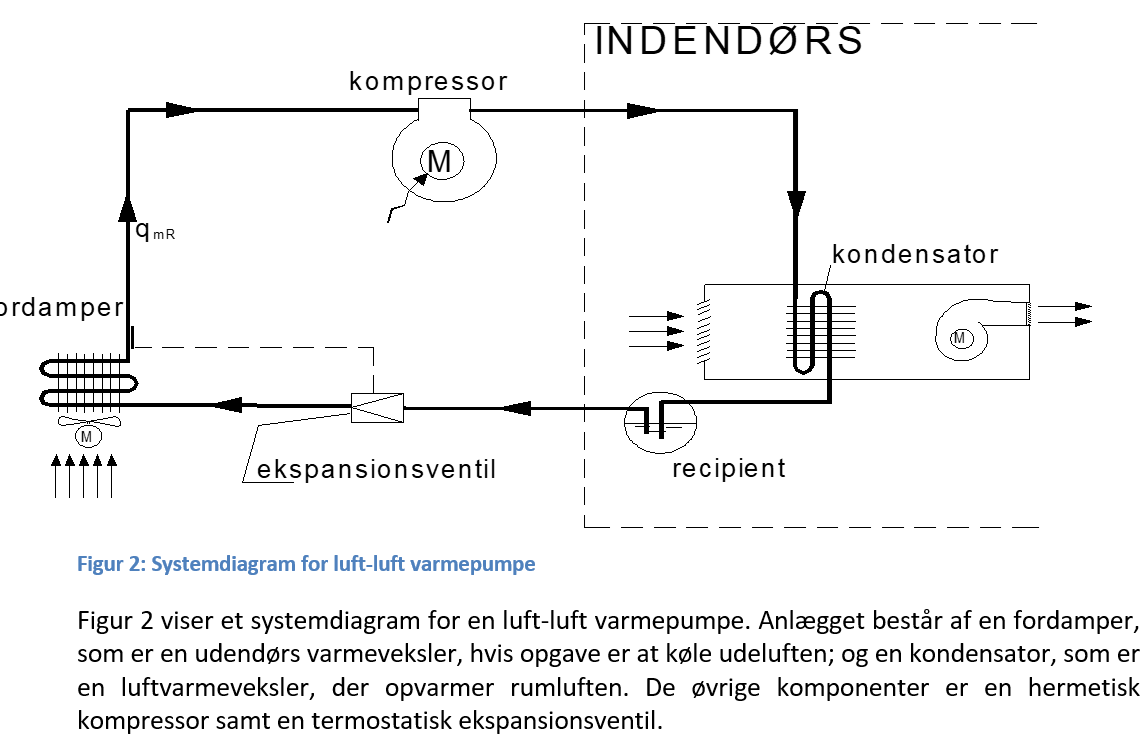

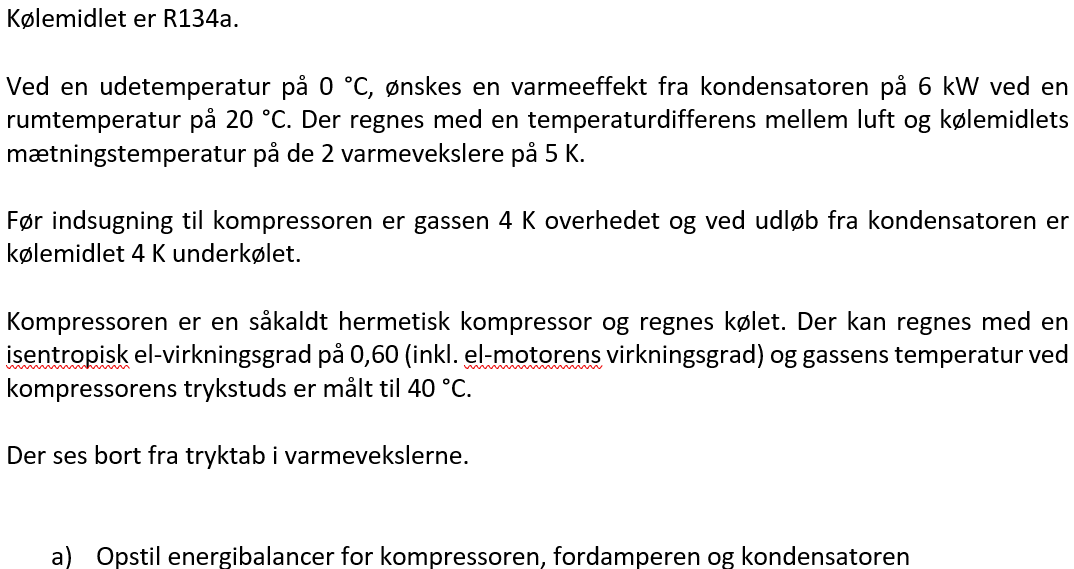

Opstiller data fra opgaven (temperatur i celsius)

T_ude = 0 %+ 273.15;

T_ude = 0

T_rum = 20 %+ 273.15;

T_rum = 20

T_4 = T_ude - 5

T_4 = -5

T_K = T_rum + 5

T_K = 25

T_3 = T_K - 4

T_3 = 21

T_1 = T_4 + 4

T_1 = -1

T_2 = 40 %+ 273.15

T_2 = 40

eta_isK = 0.60; %inklusiv el virkningsgrad

Opstiller energiligningerne

syms q_mR h_1 h_2 h_3 h_4 Phi_kol Phi_K Phi_0 P_el
eq_energi_1 = q_mR * (h_1 - h_2) - Phi_kol + P_el == 0 % kompressor

$$eq\_energi\_1 = P_{\mathrm{el}}-\Phi_{\mathrm{kol}}+q_{\mathrm{mR}}\,\left(h_{1}-h_{2}\right)=0$$

eq_energi_2 = q_mR * (h_2 - h_3) - Phi_K == 0 % kodensator

$$eq\_energi\_2 = q_{\mathrm{mR}}\,\left(h_{2}-h_{3}\right)-\Phi_{K}=0$$

eq_energi_3 = h_3 == h_4 % ekspansions ventil

$$eq\_energi\_3 = h_{3}=h_{4}$$

eq_energi_4 = q_mR * (h_4 - h_1) + Phi_0 == 0 % Fordamper

$$eq\_energi\_4 = \Phi_{0}-q_{\mathrm{mR}}\,\left(h_{1}-h_{4}\right)=0$$

### b) Indtegn kredsprocessen i vedlagte log *p*,*h*-diagram for kølemidlet. Diagrammet afleveres med opgavebesparelsen

Kredsprossen tegnes i coolpack med de gevne temperaturer fra opgaven (er også vedhæftede som billag)

Der benytte også den isentropisk virkningsgrad og en temperatur efter kompressoren på $40\degree C$

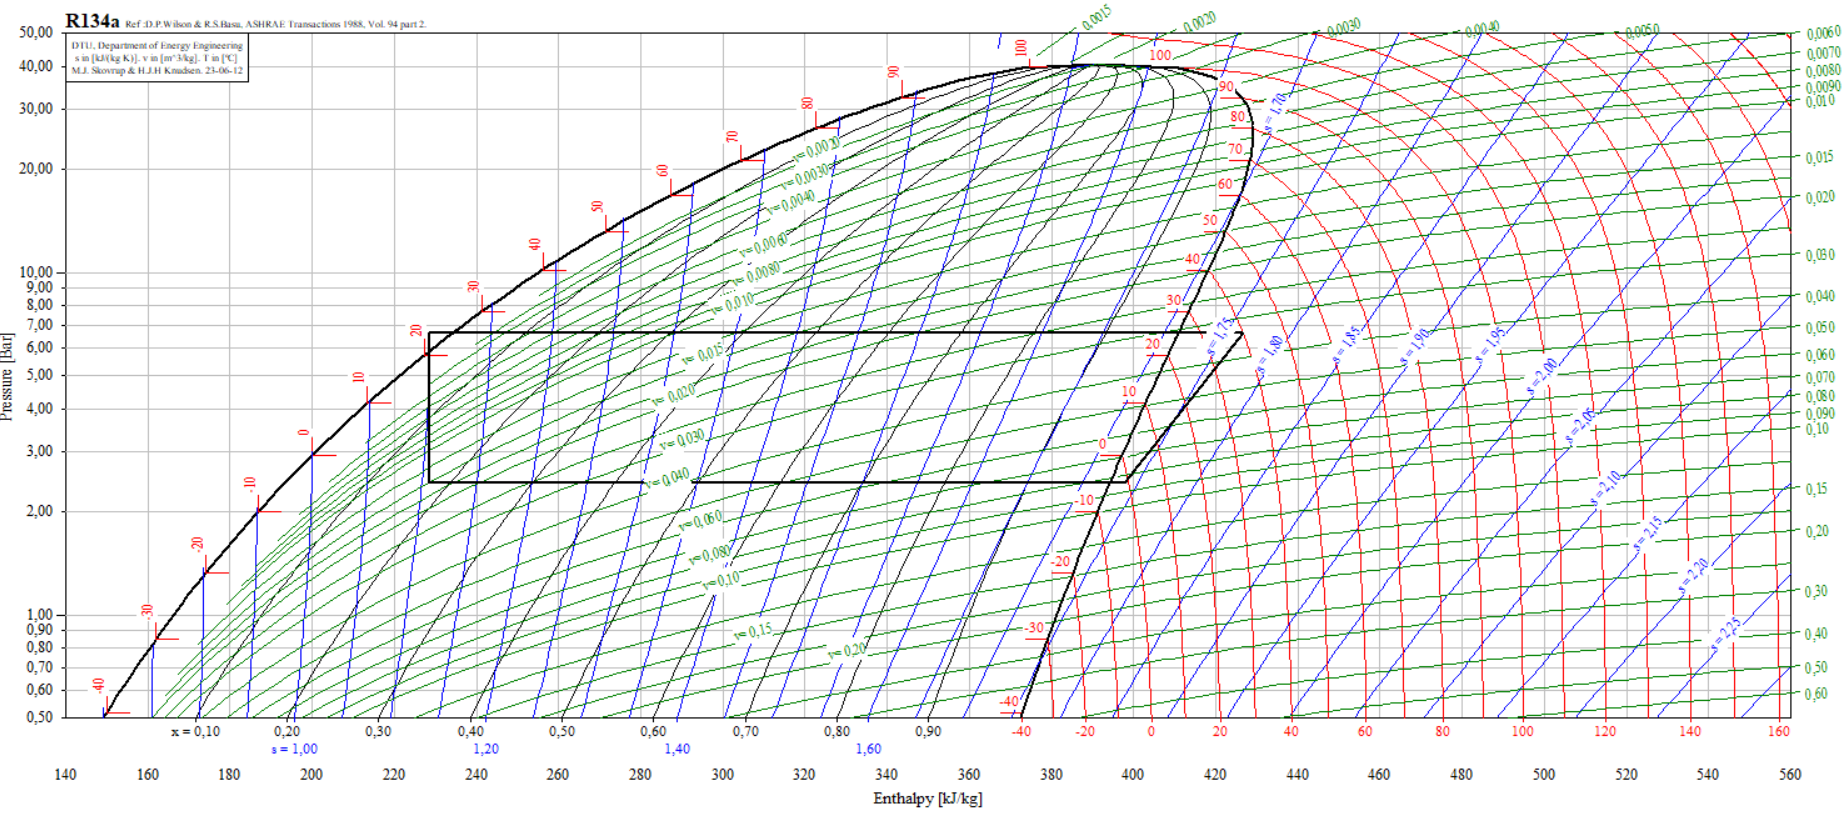

 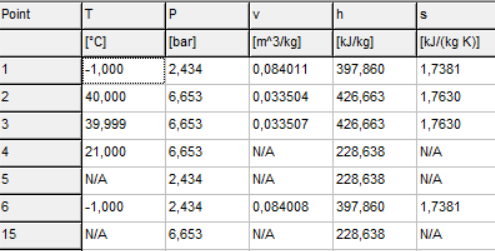

### c) Bestem den cirkulerede kølemiddelstrøm i anlægget, i kg/h

Vi benytter energiligningen for kodensatoren


$$q_{\mathrm{mR}}\,\left(h_{2}-h_{3}\right)-\Phi _{K}=0$$


Her benyttes inthalpierne fra coolpack

h_2 = 426663;
h_3 = 228638;
Phi_K = 6000;
syms q_mR
eq_energi_2 = q_mR * (h_2 - h_3) - Phi_K == 0 % kodensator

$$eq\_energi\_2 = 198025\,q_{\mathrm{mR}}-6000=0$$

q_mR = vpasolve(eq_energi_2, q_mR) %kg/s

$$q\_mR = 0.030299204645878045701300340866052$$

q_mR_h = q_mR * 3600 %kg/h

$$q\_mR\_h = 109.07713672516096452468122711779$$

Således får vi en massestrøm på $q_{mR,h} = 109,1\ \text{kg/h}$

### d) Bestem fordamperens optagne varmestrøm, dvs. kuldeydelsen

Vi benytter energiligningen for fordamperen med de fundne inthalpier fra coolåack

h_1 = 397860;
h_4 = h_3;
eq_energi_4 = q_mR * (h_4 - h_1) + Phi_0 == 0 % Fordamper

$$eq\_energi\_4 = \Phi_{0}-5127.2920085847746496654462820351=0$$

Phi_0 = vpasolve(eq_energi_4, Phi_0)

$$Phi\_0 = 5127.2920085847746496654462820351$$

Kuldeydelsen er således $\Phi_0 = 5127\ \text{W}$

### e) Bestem den tilførte el-effekt til kompressoren samt varmestrømmen som køles fra kompressoren

Vi tegner først en ekstra kredsprocess for systemet uden kompresser køling og virkningsgrad 100% for at finde P_el med de nye enthalpier fra coolpack.

Derefter kan vi løse energiligningen for kompressoren. Da vi har to ligninger med to ubekendte.

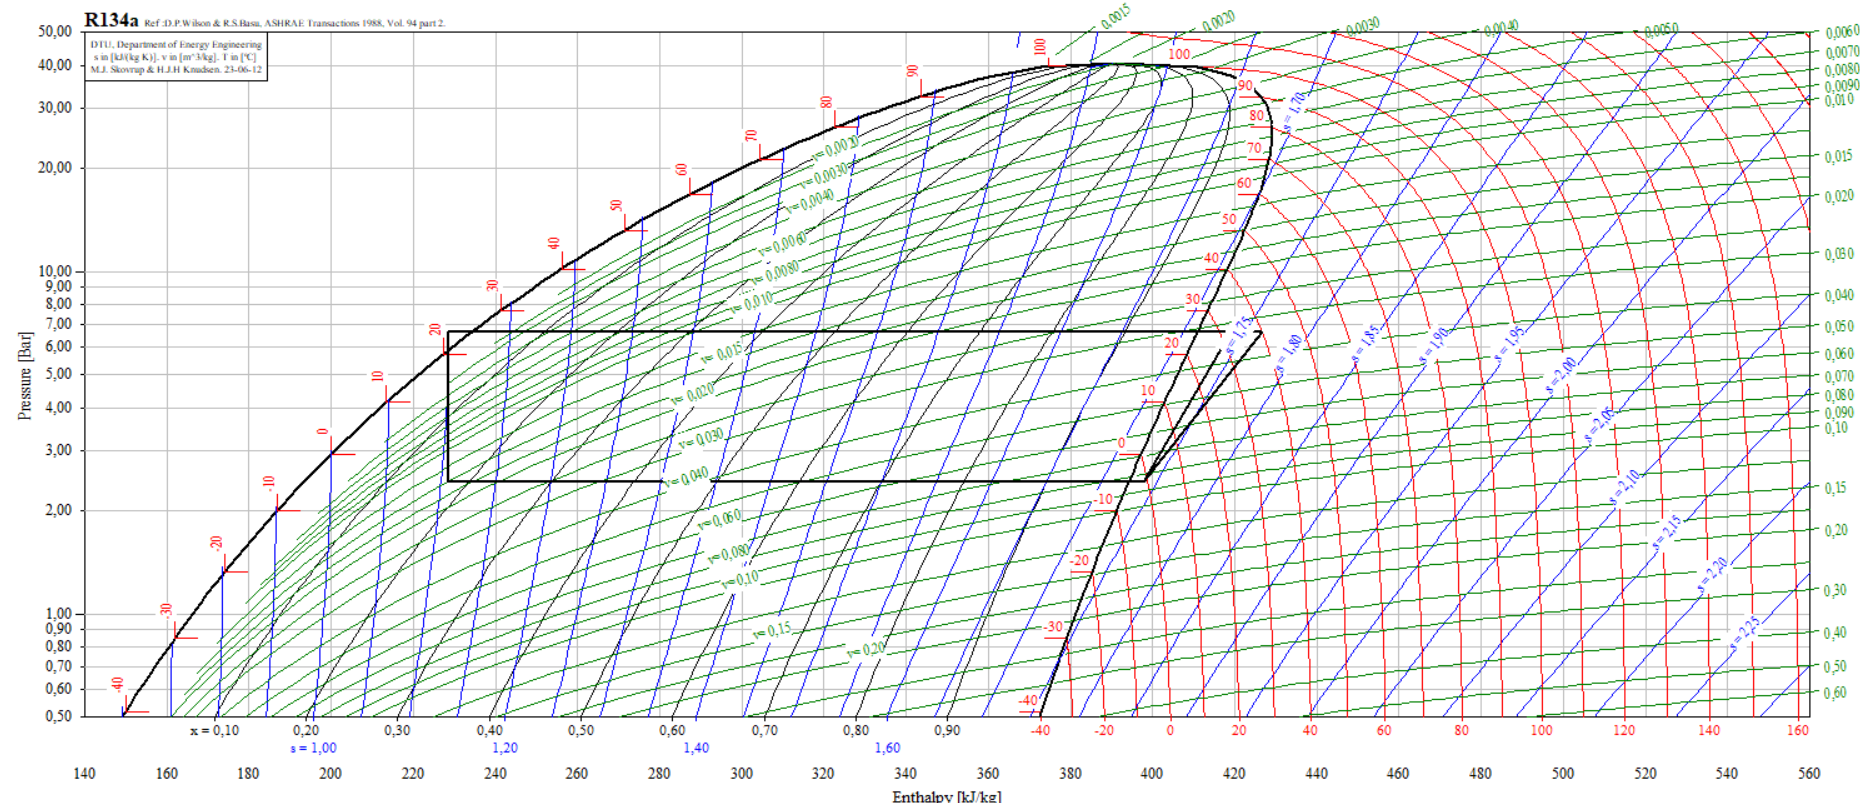

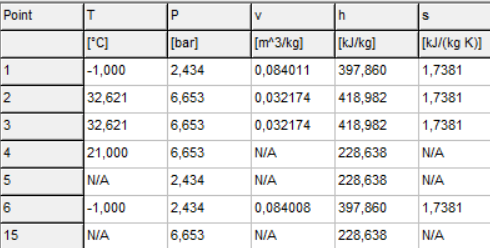

h_1

h_1 = 397860

h_2

h_2 = 426663

h_1_fri = 397860;
h_2_fri = 418982;
eq_energi_1_fri = q_mR * (h_1_fri - h_2_fri) + P_el == 0 % kompressor uden tab

$$eq\_energi\_1\_fri = P_{\mathrm{el}}-639.97980053023608130286579977276=0$$

P_el = vpasolve(eq_energi_1_fri, P_el)

$$P\_el = 639.97980053023608130286579977276$$

Vi indsætter nu ind i energiligningen med tab

eq_energi_1 = q_mR * (h_1 - h_2) - Phi_kol + P_el == 0 % kompressor

$$eq\_energi\_1 = -\Phi_{\mathrm{kol}}-232.72819088498926903168791819215=0$$

Phi_kol = vpasolve(eq_energi_1, Phi_kol)

$$Phi\_kol = -232.72819088498926903168791819215$$

Således for vi en tilført el-effekt på $P_{el} = 640\ \text{W}$

og en kølling på $\Phi_{kol} = 233\ \text{W}$

### f) Bestem varmepumpens effektfaktor og effektfaktor for den tilsvarende Carnotproces mellem udetemperatur og rumtemperatur

Effektfaktoren findes med ligning 5.12 fra lærebogen

COP = Phi_0/P_el

$$COP = 8.0116466243726919799261433576366$$

og vi får således en COP på 8,0

For Carnot processen kan vi beskrive den som

T_rum_K = T_rum + 273.15;
T_ude_K = T_ude + 273.15;
e_carnot = (T_rum_K - T_ude_K) / T_rum_K

e_carnot = 0.0682

Carnot effektiviteten er således 6,8%.

clear all
clf

% Importer CoolProp-modul
CoolProp = py.importlib.import_module('CoolProp.CoolProp');

% Stof (kan ændres efter behov)
fluid = 'Water';

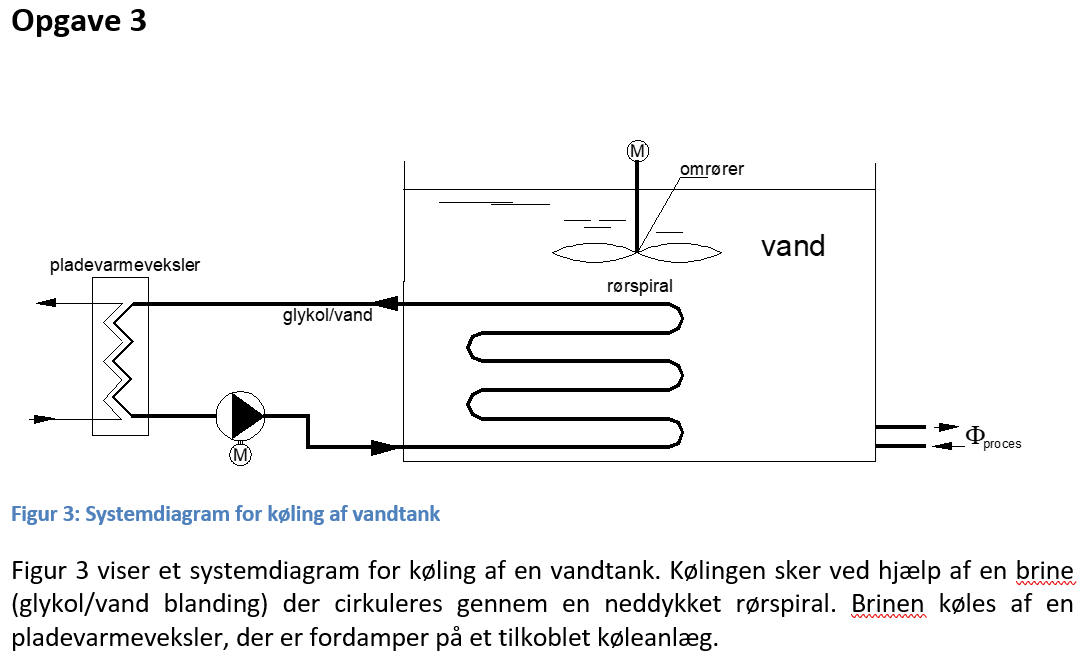

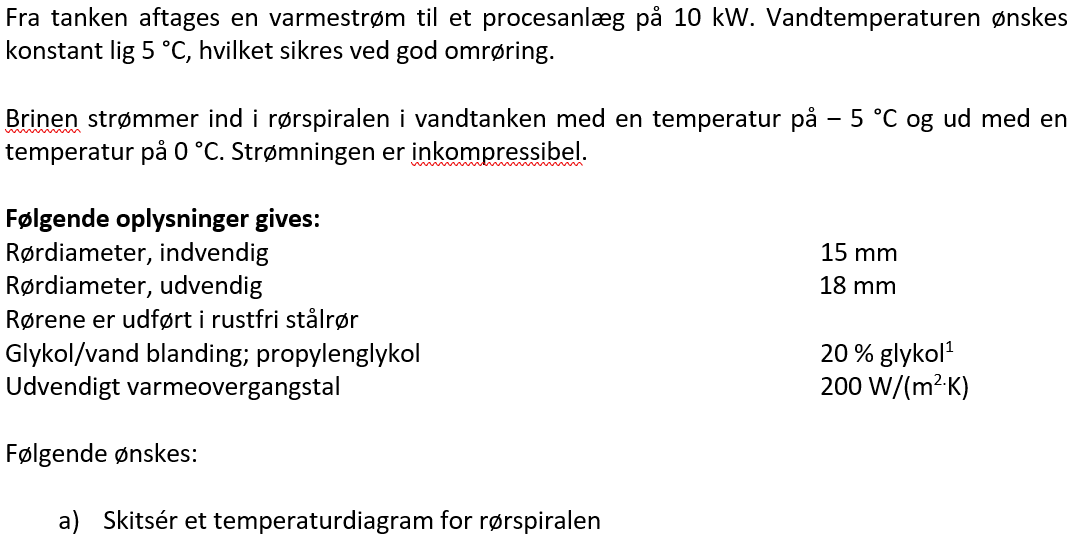

Der er -5 grader i midten af røret idet brinen fremløber og 0 grader når det når retur.

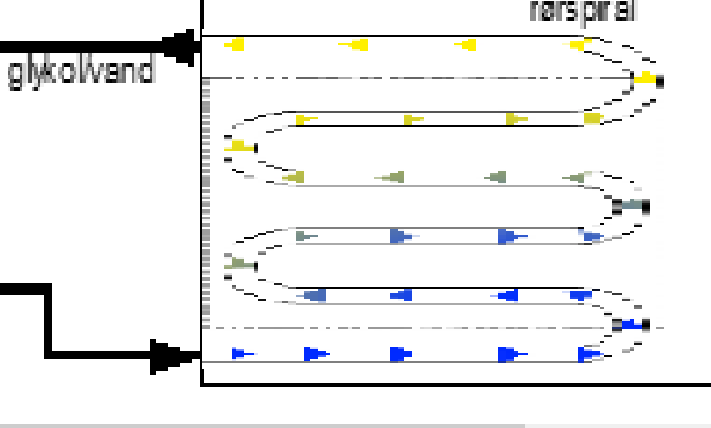

Film laget vil være lidt varmere end midten af røret.

**Tværsnit af rør **

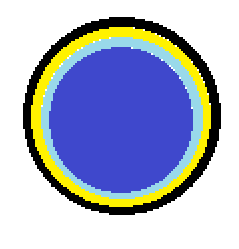

Herunder ilustrede i en graf for 5 m spiral

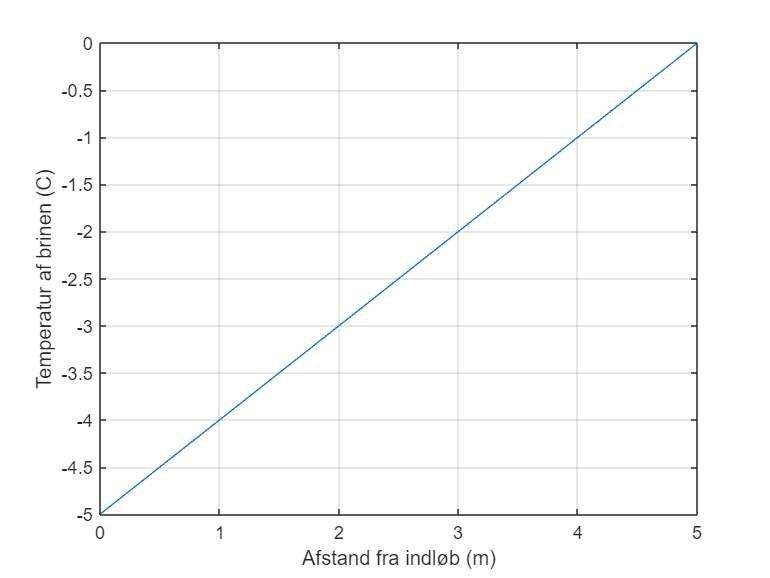

T_f = -5;
T_r = 0;
T_lin = linspace(T_f,T_r,100);
L_ror_lin = linspace(0,5,100);
plot(L_ror_lin, T_lin)
xlabel('Afstand fra indløb (m)')
ylabel('Temperatur af brinen (C)')
grid('on')

### b) Bestem hastigheden og det tilhørende Reynolds’ tal på brinesiden af rørspiralen

Phi_process = 10000 % W

Phi_process = 10000

Jeg kunne ikke finde hastigheden og bruge fremover 5 m/s

c_B = 5; %m/s

reynolds tal findes

nu_B = 1.667*1e-6;
Pr_B = 12.48;
lambda_B = 0.5652;
c_pB = 4200;
rho_B = 1000;
d_i = 0.015;
d_u = 0.018;

eta_B = nu_B * rho_B

eta_B = 0.0017

Re_B = c_B * d_i / nu_B

Re_B = 4.4991e+04

Det ses at Reynoldstal er større end 2320 og der er derfor turbolent strømning.

### c) Bestem det indvendige varmeovergangstal og bestem derefter varmegennemgangstal *U *for rørspiralen henført til den udvendige diameter

Varmeovergangstallet $\alpha$ findes med nussels tal for turbulent strømning inde i rør

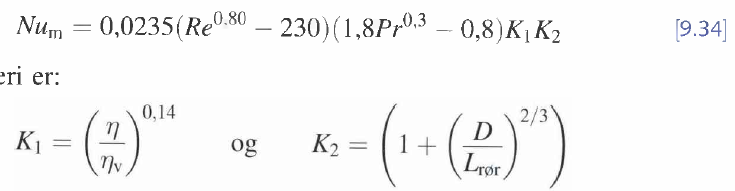

syms L

K_1 = 1 % Vi estemiere at væg temperaturen er tæt på fluid temperaturen

K_1 = 1

K_2 = (1 + (d_i/L)^(2/3))

$$K\_2 = {\left(\frac{3}{200\,L}\right)}^{2/3}+1$$

Nu_B = 0.0235*(Re_B^0.8 - 230) * (1.8 * Pr_B^0.3) * K_1 * K_2

$$Nu\_B = \frac{250337830430375\,{\left(\frac{3}{200\,L}\right)}^{2/3}}{549755813888}+\frac{250337830430375}{549755813888}$$

alpha = Nu_B * lambda_B / d_i

$$alpha = \frac{4716364725308265\,{\left(\frac{3}{200\,L}\right)}^{2/3}}{274877906944}+\frac{4716364725308265}{274877906944}$$

Her for vi alpha hvis vi kender L. Kunne ikke finde en anden metode.

### d) Bestem længden af rørspiralen

Vi opstiller følgende ligninger

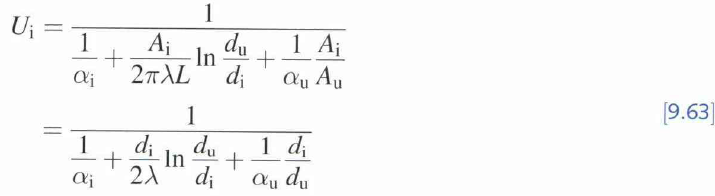


$$A_i = \pi d_i L$$


Når vi kender $U_i$ og $\alpha$ for brinen og vandet så kan vi løse ligningen for L

### e) Angiv hvilken af de indgående termiske modstande, der har størst betydning for rørlængden

Dette vil være filmlaget ved rør til vand hvis omrøren ikke skaber kraftig nok turbolent strømning til at bryde film laget eller vil det være filmlaget på indvendgside af røret.